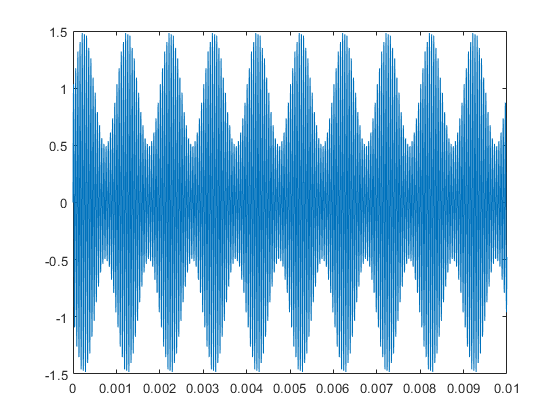

%zad1
tx=0.01;
fp=250000;
fm=1000;
m=0.5;
fn=20000;
t=(0:1/fp:tx-1/fp);
AM=(1+m*sin(2*pi*fm*t)).*sin(2*pi*fn*t);
plot(t,AM);

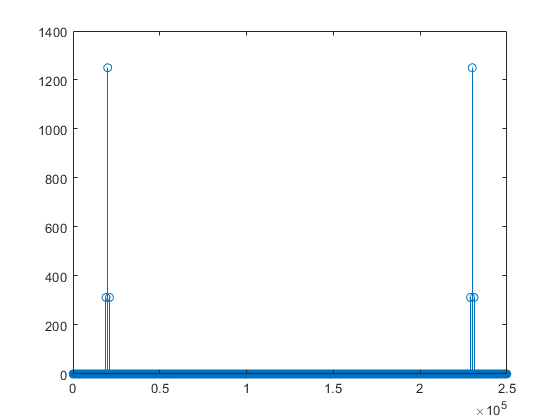

f=1/tx*(0:length(t)-1);
stem(f,abs(fft(AM)));

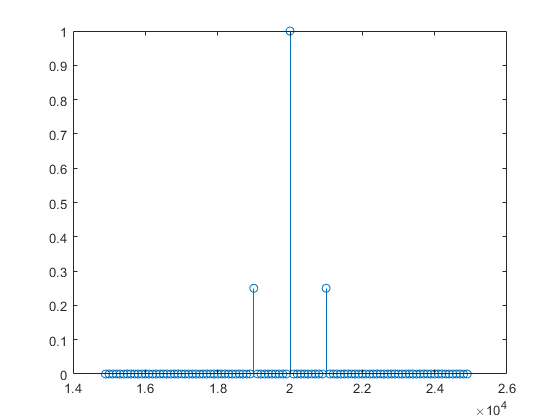

x=f(150:250);
y= abs(fft(AM))/(tx*fp/2);
y=y(150:250);
stem(x,y);

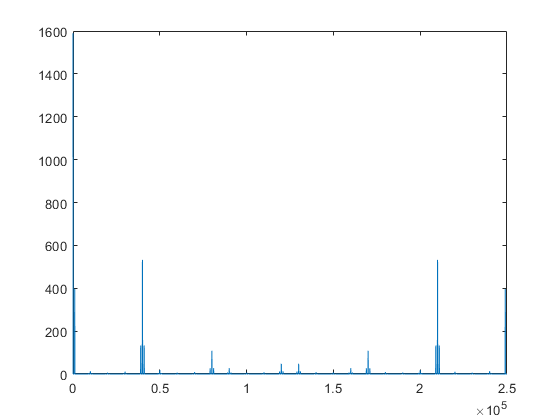

%zad2
AM_abs=abs(AM);
plot(f,abs(fft(AM_abs)));

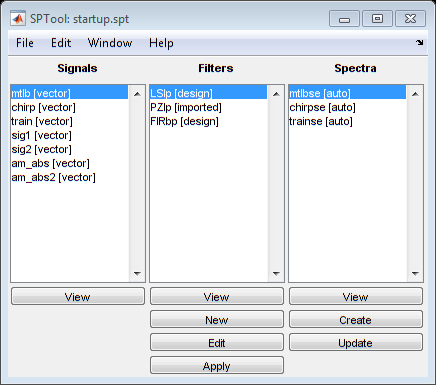

sptool;

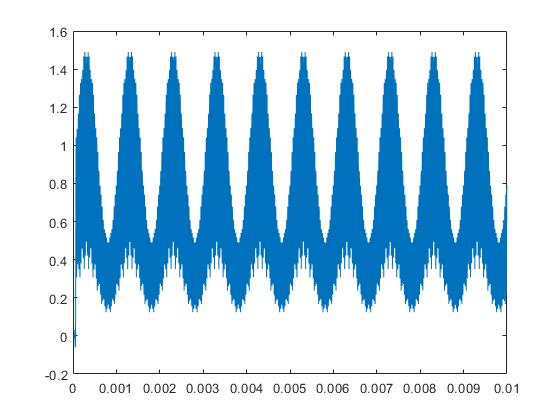


AMCW2=abs(sin(2*pi*fm*t));
f=1/tx*(0:length(t)-1);
demAM=am_abs2.data;
plot(t,demAM);

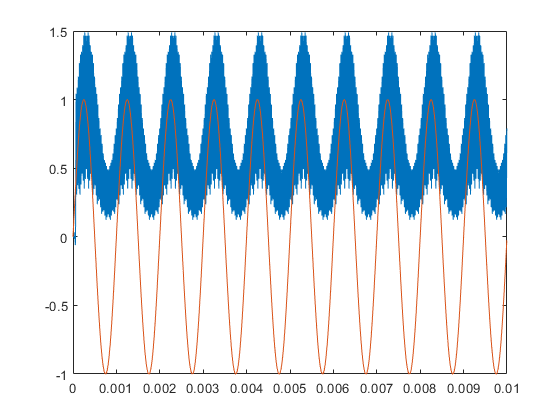

sygmod=sin(2*pi*fm*t);
plot(t,demAM,t,sygmod);

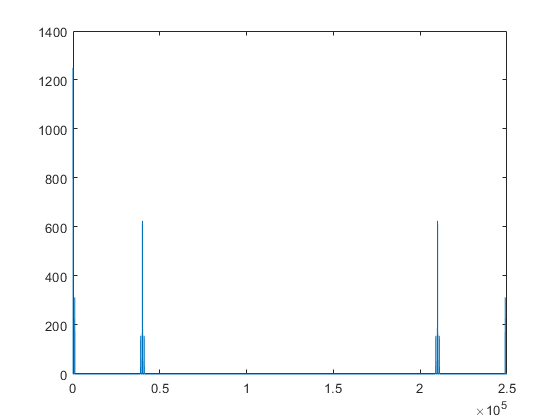

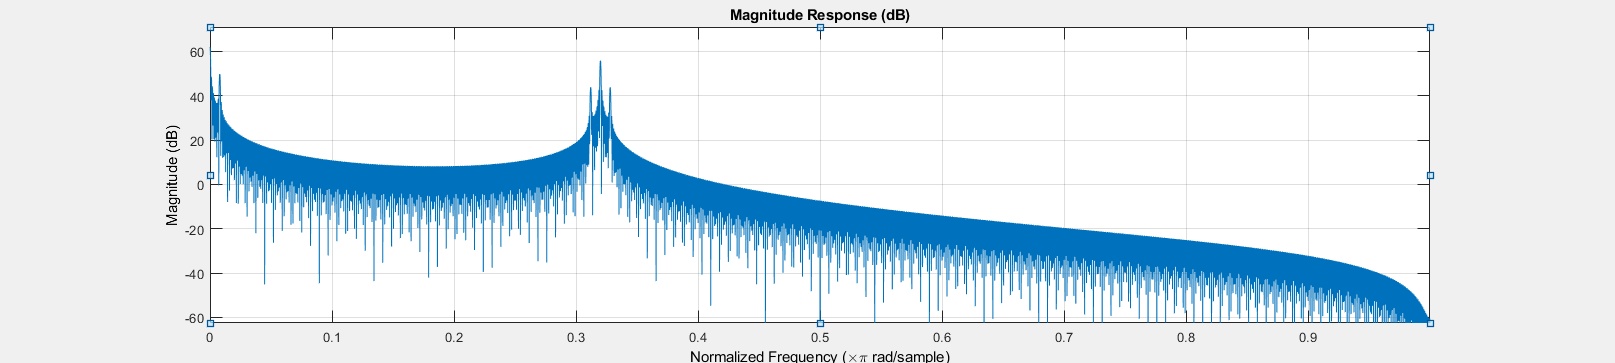


%zad3
AM_x_nosna=AM.*sin(2*pi*fn*t);
plot(f,abs(fft(AM_x_nosna)));
sptool;
fvtool(AM_x_nosna);

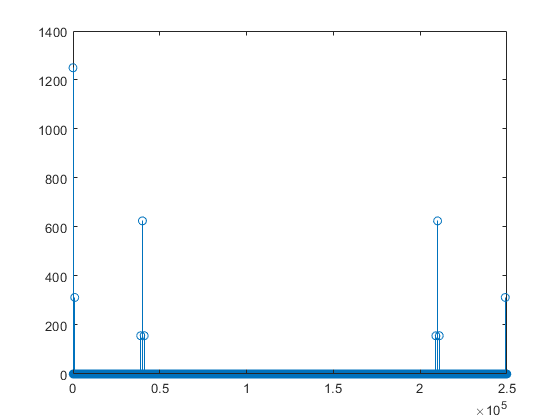

f=1/tx*(0:length(t)-1);
stem(f,abs(fft(AM_x_nosna)));

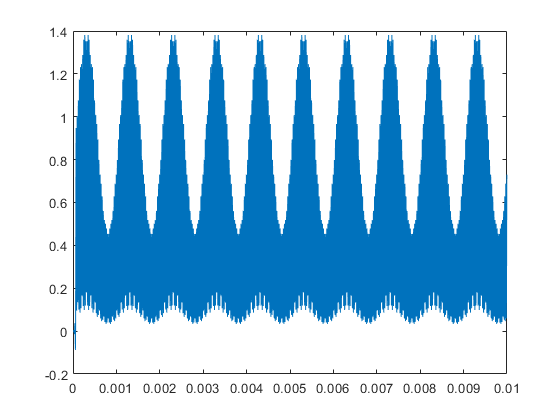

demAMX=AMX.data;
plot(t,demAMX);

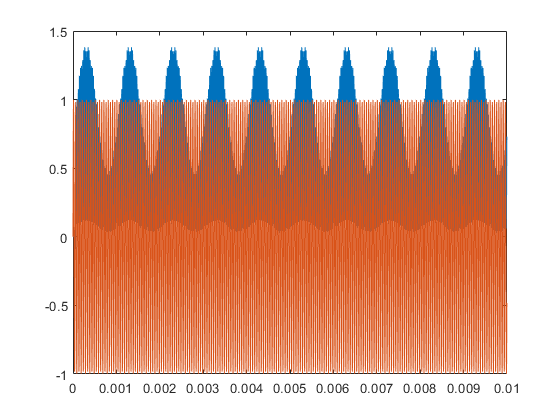

sygmod=sin(2*pi*fn*t);
plot(t,demAMX,t,sygmod);

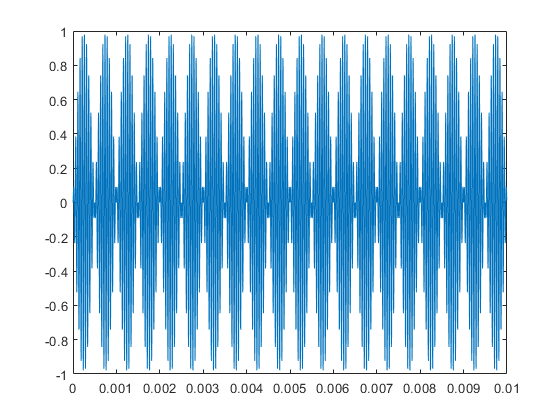

%zad4
tx=0.01;
fp=250000;
fm=1000;
m=0.5;
fn=20000;
t=(0:1/fp:tx-1/fp);
DSB=sin(2*pi*fm*t).*sin(2*pi*fn*t);
plot(t,DSB);

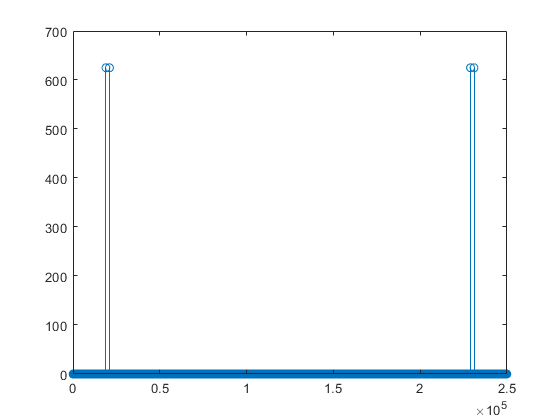

f=1/tx*(0:length(t)-1);
stem(f,abs(fft(DSB)));

demDSB=DSB1.data;
plot(t,demDSB);

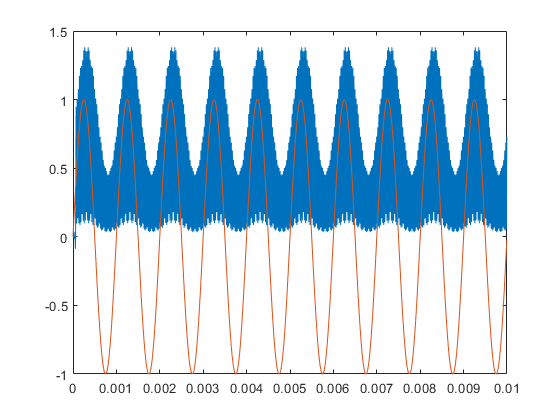

sygmod=sin(2*pi*fm*t);
plot(t,demDSB,t,sygmod);

%zad5
demDSB1=DSB1.data;
sygmod1=sin(2*pi*fn*t);
plot(t,demDSB1,t,sygmod1);

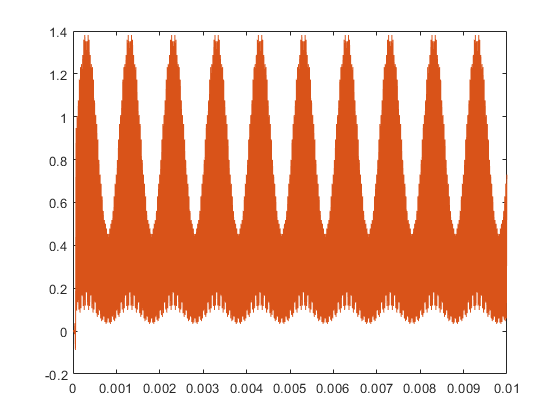

plot(t,demDSB1,t,demDSB);